NAME:- P.SAI UTTEJ

REGNO:- 19BCE7163

**1 Question**

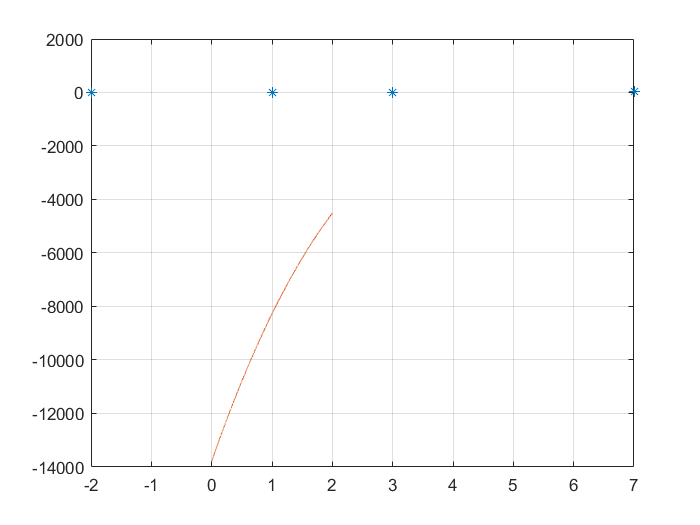

x = [ -2 1 3 7];
y = [5 7 11 34];
xx = 0:0.0001:2;
yy = lagrange_fun(xx,x,y);
plot(x,y,'*',xx,yy)
grid on

**lagrange_fun.m file**

function y = lagrange_fun(x,pointx,pointy)

n = size(pointx,2);

L = ones (n,size(x,2));

if (size(pointx,2) ~=size(pointy,2))

fprintf(1,'\nERROR!\nPOINTX and POINTY must have the same number of elements\n');

else

for i = 1:n

for j = 1:n

if (i~=j)

L(i,:) = L(i,:).*(x-pointx(i)-pointx(j));

end

end

end

y = 0 ;

for i = 1:n

y = y+pointy(i)*L(i,:);

end

end

2 Question


syms x
f = inline((sin(x))^2);a=0;b=pi;
n=6;
I=Trap(f,a,b,n);

h = 0.5236

S = 0

x = 0.5236

S = 0.5000

x =     0.5236    1.0472


S = 2.0000

x =     0.5236    1.0472    1.5708


S = 4.0000

x =     0.5236    1.0472    1.5708    2.0944


S = 5.5000

x =     0.5236    1.0472    1.5708    2.0944    2.6180


S = 6.0000

S = 6.0000

I = 1.5708

**Trap.m function file**

function I=Trap(f,a,b,n)

h=(b-a)/n

S=f(a)

for i = 1:n-1

    x(i)=a+h*i

    S=S+2*f(x(i))

end

S=S+f(b)

I=h*S/2

**3 QUESTION**

func_vec = [3 7 11 9 3];
a = 0;
b = 8;
n = length(func_vec)-1;
h = (b-a)/n;
f_1 = sum(func_vec(2:2:end-1));  
f_2 = sum(func_vec(3:2:end-2));
I = h/3*(func_vec(1) + 4*f_1 + 2*f_2 + func_vec(end));
I

I = 61.3333